Control Digital - Entrega 2 - predictor de Smith y controlador RST

Arthur de La Lande

- **Implementación de predictor de Smith y validación de desempeño.**

La planta que hemos estudiado en este proyecto comporta un retardo. Este retardo afecta la estabilidad del sistema porque aumenta la cantidad de polos del sistema en lazo cerrado.

Tomemos el controlador PID hallado por metodo de Ziegler-Nichols.

Recuerdos del modelo de la planta de primer orden con atraso:

K=0.0604; tau=15.7; theta=2.2; Ts=6.6139;
F=tf(K,[tau,1],"InputDelay",theta)

F =
 
                  0.0604
  exp(-2.2*s) * ----------
                15.7 s + 1
 
Continuous-time transfer function.
Model Properties


Recuerdos de los parametros del PID:

Kp=15.3692 ; Ti=4.1888 ;Td=1.0472 ;
q0=Kp*(1+Ts/(2*Ti)+Td/Ts), q1=Kp*(Ts/(2*Ti)-2*Td/Ts-1), q2=Kp*Td/Ts

q0 = 29.9362

q1 = -8.1025

q2 = 2.4335

El objetivo de sintonizar un predictor de Smith es simular un sistema de control como si la planta no estuviera atrasada, al cual se agregaria el atraso a la salida. Eso permite que que en la simulación, el atraso no entre en el lazo de control, lo que reduce la inestabilidad.

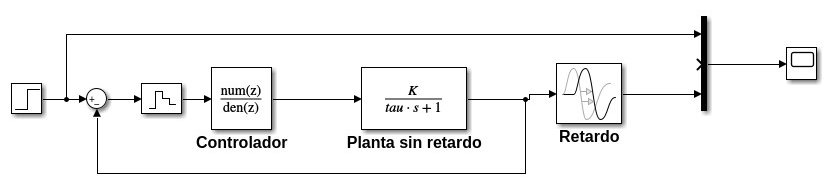

Fig : Diagrama de bloques de la estrategia de control con aislamiento del retardo (teorico)

En la realidad no se puede medir la salida de la planta sin el atraso por lo que la planta es un bloque indivisibe. Vamos entonces con logica de bloques a simular como si la retroalimentación del sistema en LC fuera la salida de la planta sin atraso pero con una medida real que se origina con la planta real, quiere decir atrasada.

F_sr=tf(K,[tau,1]) % El modelo de la planta sin atraso.

F_sr =
 
    0.0604
  ----------
  15.7 s + 1
 
Continuous-time transfer function.
Model Properties


Fd_sr=c2d(F_sr,Ts) % El modelo de la planta sin atraso discretizado.

Fd_sr =
 
   0.02076
  ----------
  z - 0.6562
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


Se comprueba por algebra de bloques que el sistema es equivalente al siguiente (y se verifica con los desempeños de las respuestas que son iguales):

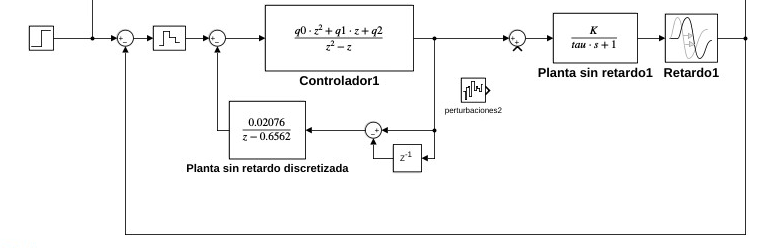

Fig: diagrama de bloques de control del modelo de la planta con implementación realista de un predictor de Smith.

Donde z^-1 es el retardo en tiempo discreto.

Podemos ahora comparar los desempeños de las diferentes estrategias: control con PID clasico y control con implementación de predictor de Smith:

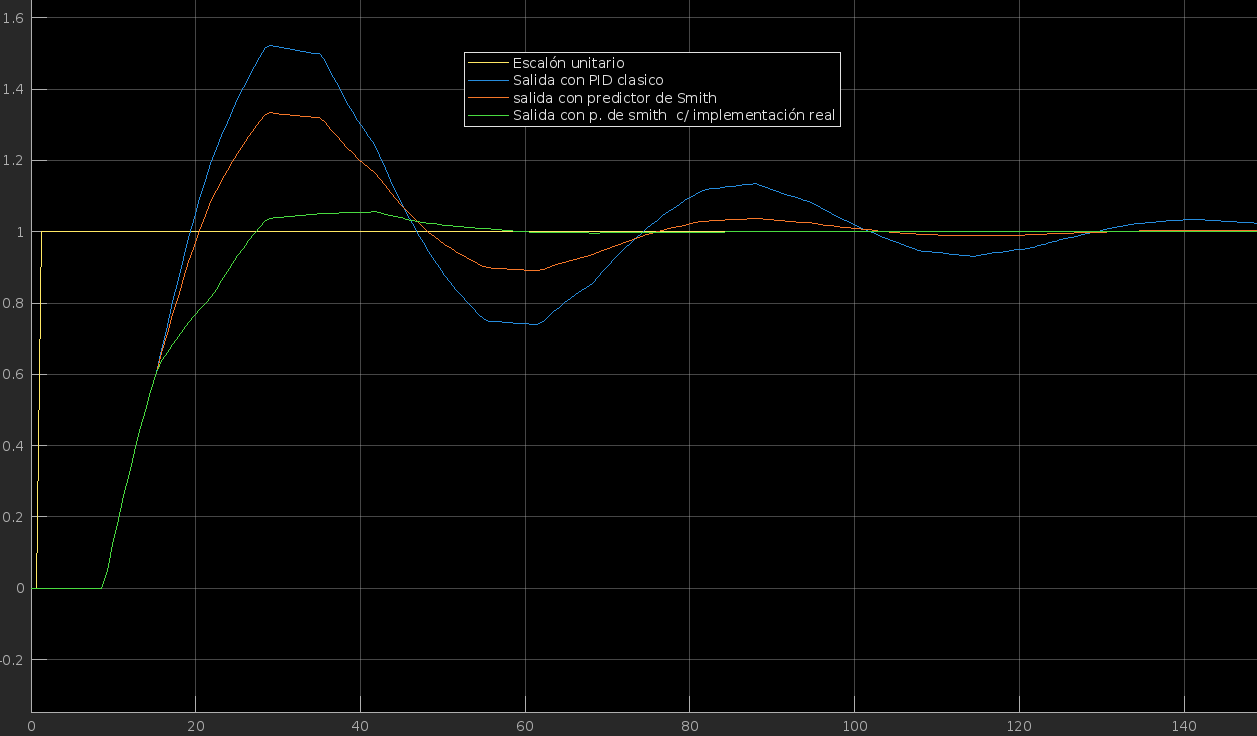

Fig: Entrada escalón unitario y respuestas de la planta ante una correción PID, una correción PID + predictor de Smith (teorico y implementación real)

Este grafico muestra el relativamente mal desempeño de la planta con un controlador PID (muchos sobreimpulsos, tiempo de establecimiento largo), frente al mejor deesempeño de la planta con predictor de Smith. El sobreimpulso es bien menor aunque largo en tiempo.

Ahora agregamos perturbaciones para comparar los desempeños:

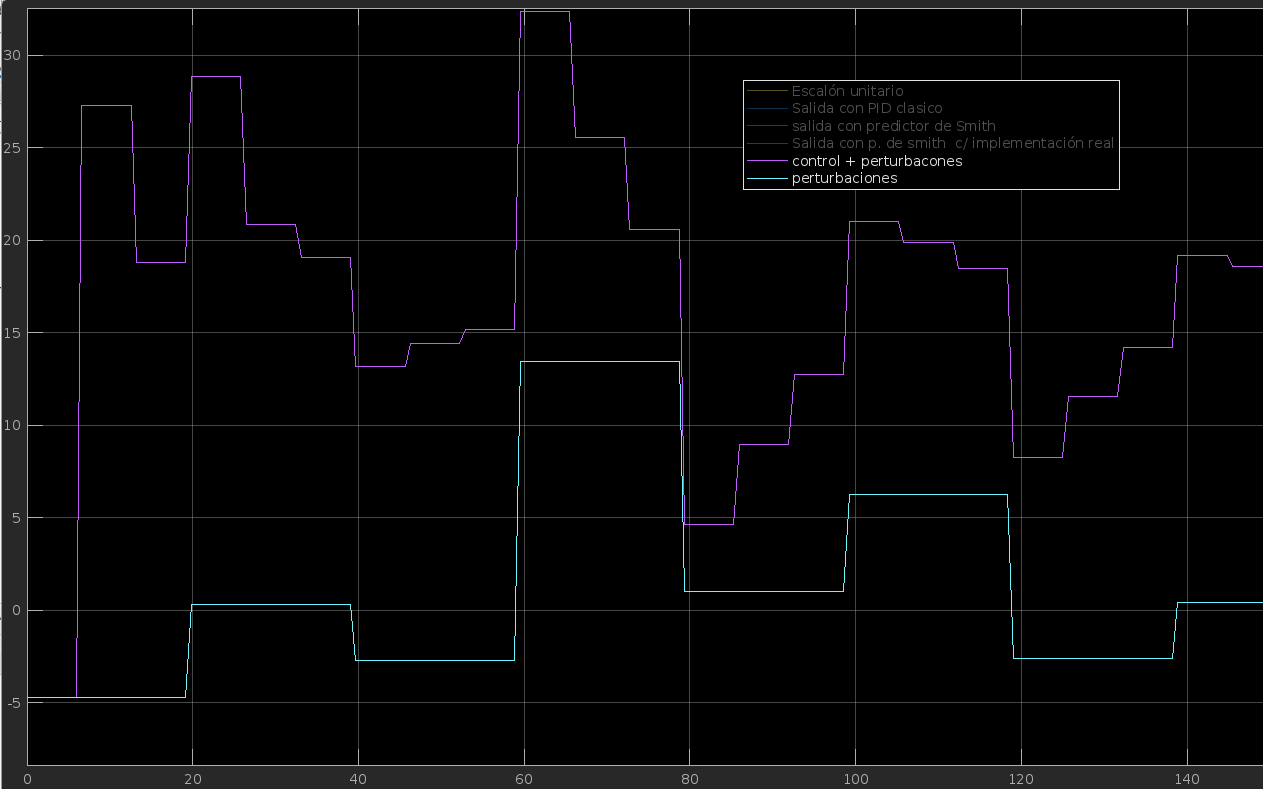

Fig: comando de control con perturbaciones y perturbaciones puras

Este grafico nos permite mirar el impacto que tienen las perturbaciones sobre el comando de la planta y tambien nos muestra la rapidez con la cual el controlador lo corrige.

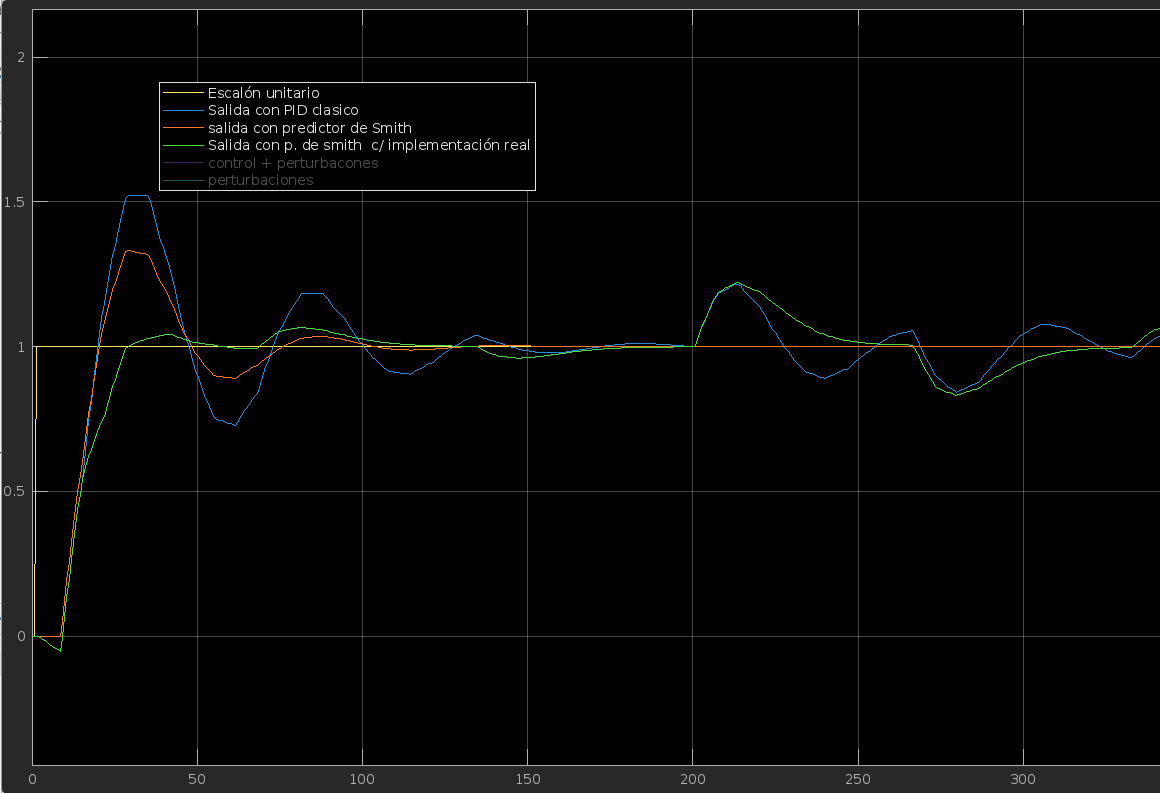

Fig: Desempeño del modelo de la planta con un PID y un PID+predictor de Smith, con perturbaciones.

Las perturbaciones son escalones que se suman a la salida del controlador y perturban el buen control de la planta por generar un comando aleatorio. Este grafico muestra que el predictor de Smith logra controlar mejor las perturbaciones que el PID clasico. En efecto nunca genera sobre impulsos de "respuesta" a una perturbación en escalón.

**2. Implementación de un controlador RST incremental y validación de desempeño.**

Fd=c2d(F,Ts) % El modelo de la planta discretizado, sin atraso

Fd =
 
           0.0148 z + 0.005962
  z^(-1) * -------------------
               z - 0.6562
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


Fd es de la forma Fd=z^(-d)*B/A, donde :

d=1

B=0.0148 + 0.005962 z^(-1)

A=1 - 0.6562 z^-1

El retardo en esta función de transferencia es de 1 muestra. Cuando hallemos los parametros de los modulos del RST, nos vamos a encontrar con una ecuación caracteristica Q(z) con un grado de 1.

Busquemos los coeficientes de los modulos R(z),S(z) y T(z).

- Grado de S: ns=na=1

- Grado de R: nr=nb+d-1=1+1-1=1

Utilizando el metodo de asignación de polos para determinar los coeficientes de R y S:

Q(z)=A(z)*R(z)*(1-z^-1)+z^(-d)*B(z)*S(z)

Este polinomio lo queremos igualar a un polinomio de primer orden : Q(z)=1-p1*z^(-1).

p1=0.7;

Igualamos  los terminos de cada potencia de z para resolver este sistema de 4 incognitas.

r0=1; r1=0.2824; s0=45.5287; s1=-31.0792;

t0 = 14.4495

Para encontrar T(z), aplicamos el teorema del valor final (la entrada es igual a la salida en z=1)

T(1) = S(1)

t0=s0+s1

Ahora podemos simular el RST incremental en Simulink y ver su desempeño.

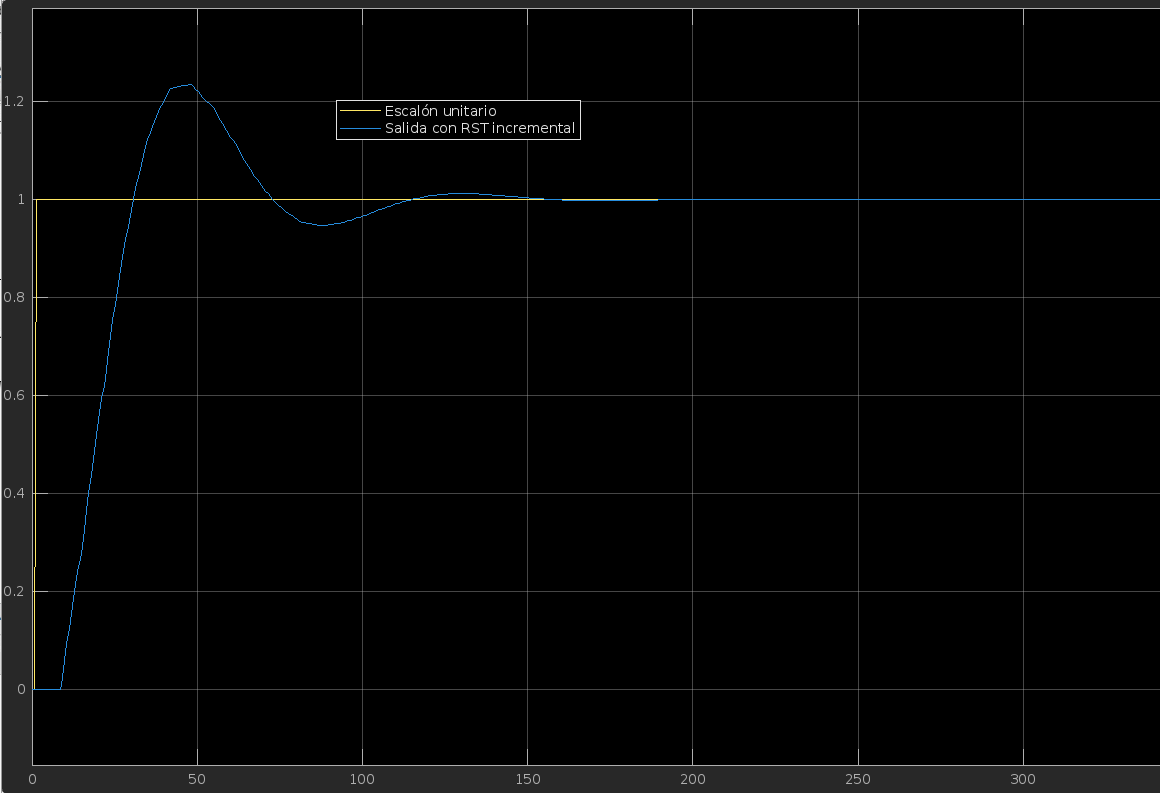

Fig: Desempeño del modelo de la planta controlado con un RST incremental.

El desempeño esta rapido y preciso, pero tiene sobreimpulsos que pueden ser significativos dependiendo de nuestros criterios de desempeño. Ahora miremos como reaccione el sistema ante perturbaciones y cambios de referencia:

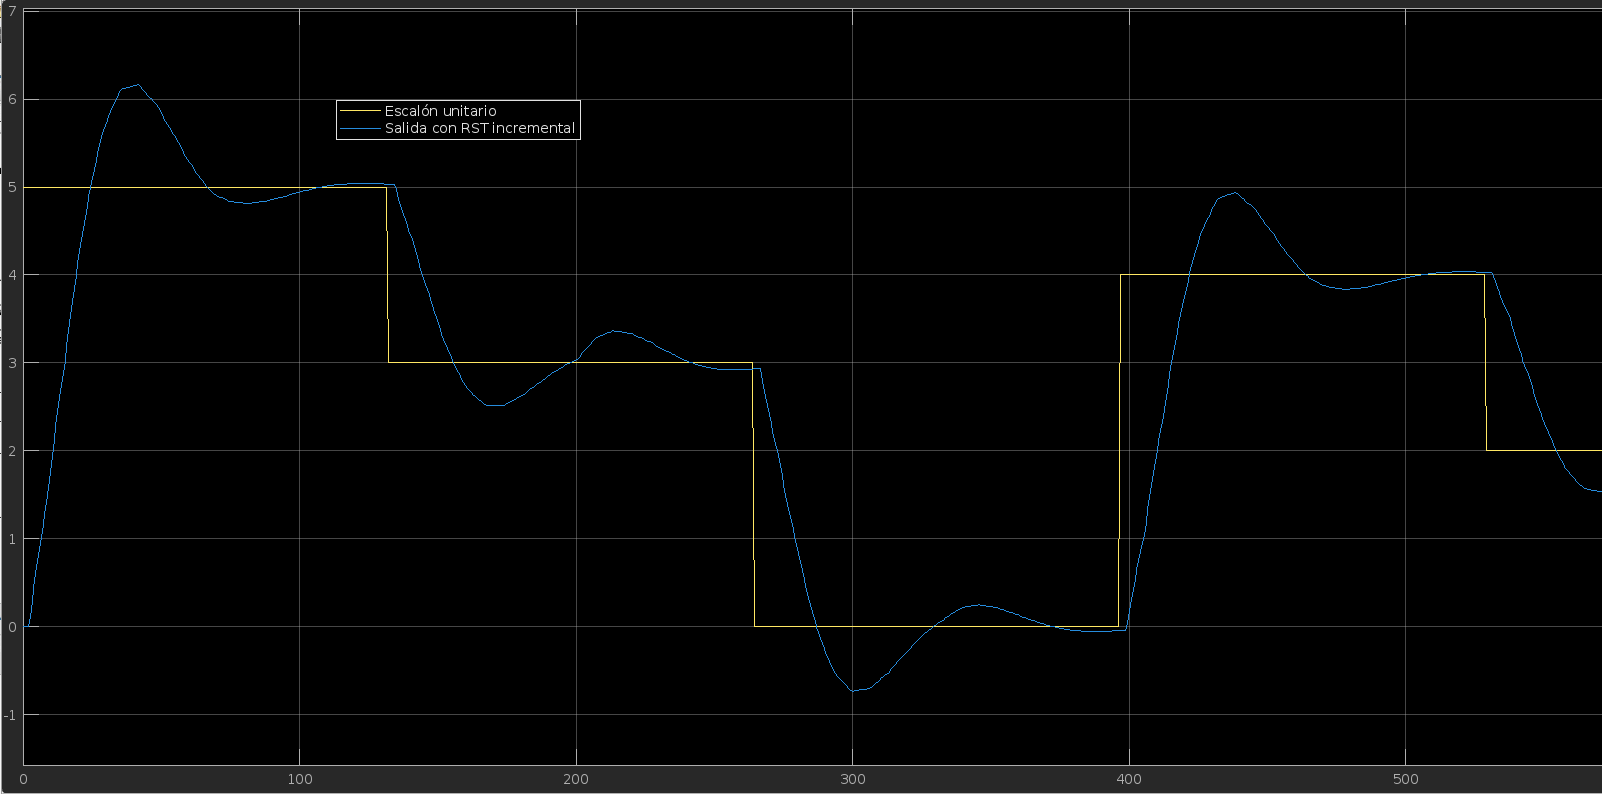

Fig: Desempeño del modelo de la planta controlado con un RST incremental, con perturbaciones y cambios de referencia

Para concluir, en este desempeño casi no se ven las perturbaciones que vienen cambiar la entrada de la planta. Podemos decir que el rechazo de estas perturbaciones es total, gracias a la caracteristica "incremental" del RST.